# Kolokwium zaliczeniowe

### Imię i nazwisko:

### Grupa zajęciowa:

# Część I. Analiza wizualizacji danych (10 punktów)

- Dokonaj analizy poniższego wykresu pod względem wizualnego sposobu przekazu. Wypisz wady (i ewentualnie zalety) przedstawionej wizualizacji danych na tym wykresie. 

- Zaporponuj inny (lepszy) sposób (nie wystarczy podać typu wykresu!), aby można było łatwo odczytać i analizować dane.

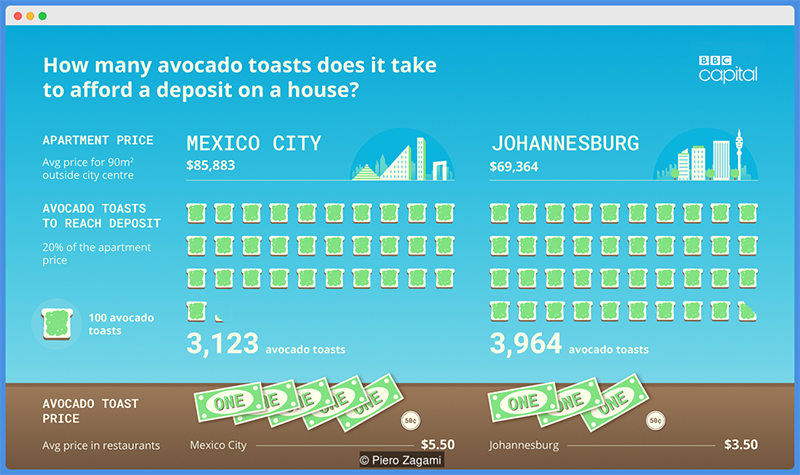

# Część II. Matlab (20 punktów)

Zadanie 1. (5 punktów)

Rozwiąż układ równań wykorzystując wyznaczenie macierzy odwrotnej.

Oblicz wyznacznik główny danego układu równań.

close all
clear 
A = [1 4 -5 0; -5 3 -1 -1; -2 -6 0 2; 1 1 1 1];
B = [0; 4; -6; 12];
syms a b c d
[a; b; c; d] == inv(A)*B

$$ans = \left(\begin{array}{c} a=-\frac{3}{5}\\ b=\frac{17}{5}\\ c=\frac{13}{5}\\ d=\frac{33}{5} \end{array}\right)$$

syms x y z w
[x; y; z; w] == A \ B

$$ans = \left(\begin{array}{c} x=-\frac{3}{5}\\ y=\frac{17}{5}\\ z=\frac{13}{5}\\ w=\frac{33}{5} \end{array}\right)$$

Zadanie 2. (15 punktów)

Mając dane cereal.mat

a) wykreśl dane cukrów oraz protein. Pamiętaj o wszystkich elementach dobrej wizualizacji. (10 pkt)

b) wyznacz średnie wartości oraz narzuć na wykres. (3 pkt)

c) jakie były największe wartości witamin oraz kalorii? (2 pkt)

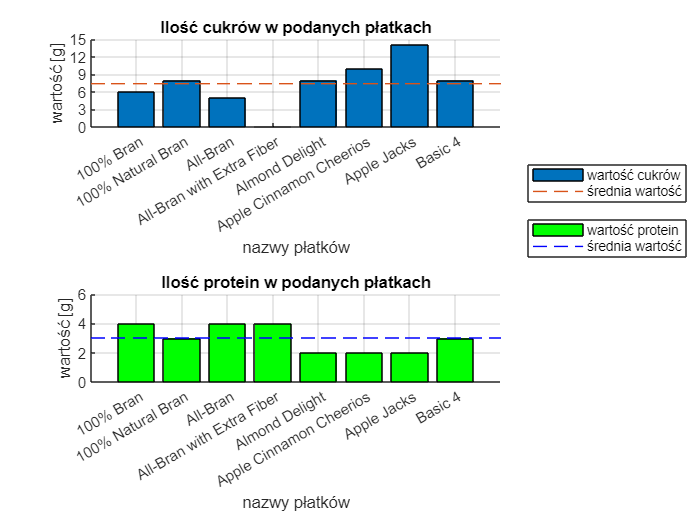

close all
clear
load cereal.mat
nazwy = categorical([Name(1:8,1:size(Name, 2))]);
nazwy = reordercats(nazwy,[Name(1:8,1:size(Name, 2))]);
witaminy = Vitamins(:,1);
kalorie = Calories(:,1);

proteiny = Protein(1:8,:);
cukry = Sugars(1:8,:);


figure

nexttile
hold on
bar(cukry)
syms y 
y = mean(cukry);
fplot(y,'--')
xticklabels(nazwy)
xticks(1:1:8)

ylim([0,15])
xlim([0,9])
yticks(0:3:15)
xlabel('nazwy płatków')
ylabel('wartość [g]')
title('Ilość cukrów w podanych płatkach')
grid
hold off
lgd = legend('wartość cukrów', 'średnia wartość');
lgd.Layout.Tile = 'east';

nexttile
hold on
bar(proteiny, 'g')
syms y 
y = mean(proteiny);
fplot(y,'--b')
xticklabels(nazwy)
xticks(1:1:8)

ylim([0,6])
yticks(0:2:6)
xlim([0,9])
xlabel('nazwy płatków')
ylabel('wartość [g]')
title('Ilość protein w podanych płatkach')
grid
hold off


lgd1 = legend('wartość protein', 'średnia wartość');
lgd1.Layout.Tile = 'east';





disp('c)')

c)


max(witaminy)

ans = 100

max(kalorie)

ans = 160